syms w real
syms x(w) y(w) z(w)
assumeAlso([x(w) y(w) z(w)],'real')
assumeAlso([x(w) y(w) z(w)] ~=0) %not zero
syms a b t real
dp=@(f,g) int(f*g,-1,1); %Dot Product

%Check linearity
simplify( expand(  dp(a*x+b*y,z) - (a*dp(x,z)+b*dp(y,z))  ) )

$$ans = 0$$


%Check symmetry
expand( dp(x,y) - dp(y,x) )

$$ans = 0$$


%Check positive definitness
disp(dp(x(w),x(w)))

$$\int_{-1}^{1}{x\left(w\right)}^{2}\mathrm{d}w$$

Exercise: verify if the following is a dot product:


$$\langle x,y \rangle = y^Tx$$
    
$$\forall x,y \in \mathbb R^n$$
 
$$\iff \langle x,y \rangle = \sum_{k=1}^n x_k y_k$$


You must choose a value for n. N choosen = 5

n=5;
syms x y [n 1] real;
test=sum(x'*y,n)

$$test = x_{1}\,y_{1}+x_{2}\,y_{2}+x_{3}\,y_{3}+x_{4}\,y_{4}+x_{5}\,y_{5}$$

f=@(x,y) sum(y'*x,n)

f = function_handle with value:
    @(x,y)sum(y'*x,n)



% Check linearity
syms a b real;
syms z [n 1] real;
simplify(expand(f(a*x+b*y,z) - (a*f(x,z)+b*f(y,z)) )) %Linearity Holds

$$ans = 0$$

 
expand(f(x,y)-f(y,x)) %Symmetry Holds

$$ans = 0$$


disp(f(x,x)) %Positive Definitness holds 

$${x_{1}}^{2}+{x_{2}}^{2}+{x_{3}}^{2}+{x_{4}}^{2}+{x_{5}}^{2}$$

Now verify if the following is a dot product:


$$\langle x,y \rangle = y^Hx$$
    
$$\forall x,y \in \mathbb C^n$$
 
$$\iff \langle x,y \rangle = \sum_{k=1}^n x_k \overline{y_k}$$


You must choose  avalue for n.

n=3;
syms w real;
syms x(w) y(w) [n 1];
dp=@(g,t) sum(conj(y')*x,n)

dp = function_handle with value:
    @(g,t)sum(conj(y')*x,n)


c=conj(y) %Returns the complex conjugate

$$c(w) = \left(\begin{array}{c} \bar{y_{1}\left(w\right)}\\ \bar{y_{2}\left(w\right)}\\ \bar{y_{3}\left(w\right)} \end{array}\right)$$

A =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1



syms a b real;
syms z(w) [n 1];
simplify(expand(f(a*x+b*y,z) - (a*f(x,z)+b*f(y,z)) )) %Linearity Holds

$$ans(w) = 0$$

simplify(expand(f(x,y)-f(y,x))) %Symmetry Doesn't hold

$$ans(w) = \bar{y_{1}\left(w\right)}\,x_{1}\left(w\right)-\bar{x_{1}\left(w\right)}\,y_{1}\left(w\right)-\bar{x_{2}\left(w\right)}\,y_{2}\left(w\right)+\bar{y_{2}\left(w\right)}\,x_{2}\left(w\right)-\bar{x_{3}\left(w\right)}\,y_{3}\left(w\right)+\bar{y_{3}\left(w\right)}\,x_{3}\left(w\right)$$

Neighborhoods in metric spaces

clf;
x=[1 2 -3 -4 5];
disp([norm(x,2); norm(x,inf); norm(x,1)])

    7.4162
    5.0000
   15.0000



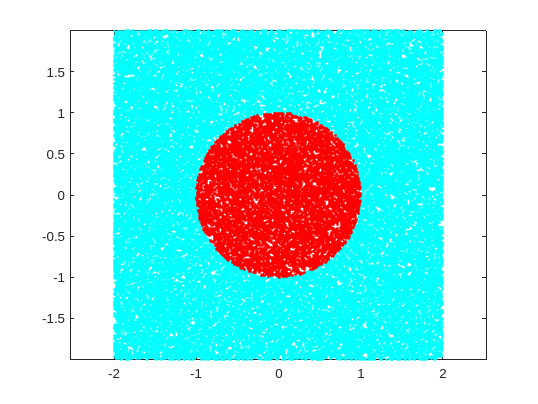

x1=-2+4*rand(1,50000);
x2=-2+4*rand(1,50000);
x=[x1;x2];
j=find(sqrt(sum(x.^2)) <=1); %Euclidean norm
plot(x1,x2,'.c',x1(j),x2(j),'.r');
axis equal;

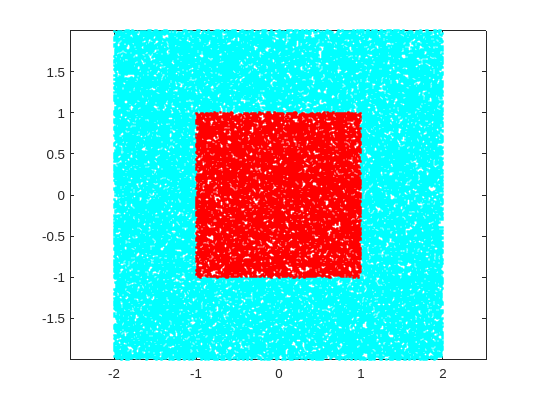


clf;
j=find(max(abs(x)) <=1); %Uniform norm
plot(x1,x2,'.c',x1(j),x2(j),'.r');
axis equal;

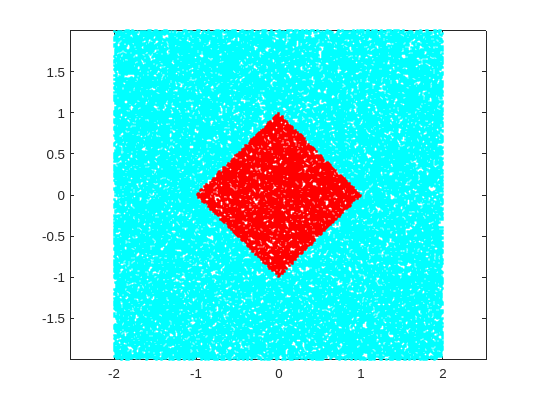


clf;
j=find(sum(abs(x))<=1); %Taxicab norm
plot(x1,x2,'.c',x1(j),x2(j),'.r');
axis equal;

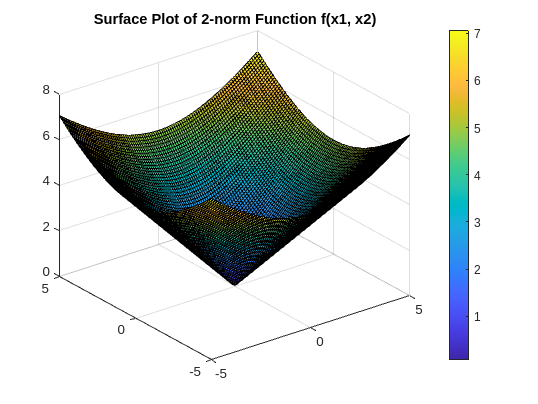

clf;
syms x1 x2;

% Define the 2-norm function
f = sqrt(x1^2 + x2^2);
% Define the range of x1 and x2
x1_range = linspace(-5, 5, 100);
x2_range = linspace(-5, 5, 100);

[x1_grid, x2_grid] = meshgrid(x1_range, x2_range);
f_values = double(subs(f, {x1, x2}, {x1_grid, x2_grid}));
surf(x1_range, x2_range, f_values); colorbar;
title('Surface Plot of 2-norm Function f(x1, x2)');

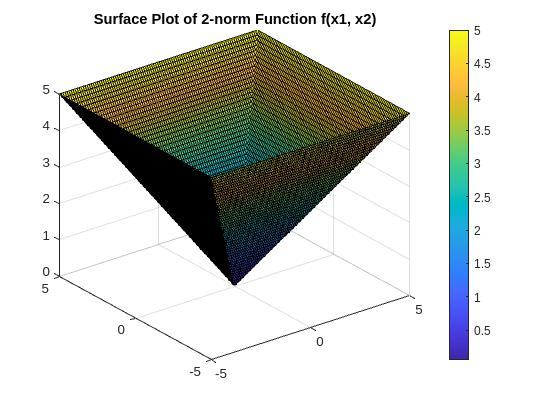


clf;
syms x1 x2;

% Define the 2-norm function
f = max(abs(x1),abs(x2));
% Define the range of x1 and x2
x1_range = linspace(-5, 5, 100);
x2_range = linspace(-5, 5, 100);

[x1_grid, x2_grid] = meshgrid(x1_range, x2_range);
f_values = double(subs(f, {x1, x2}, {x1_grid, x2_grid}));
surf(x1_range, x2_range, f_values); colorbar;
title('Surface Plot of Infinity-norm Function f(x1, x2)');

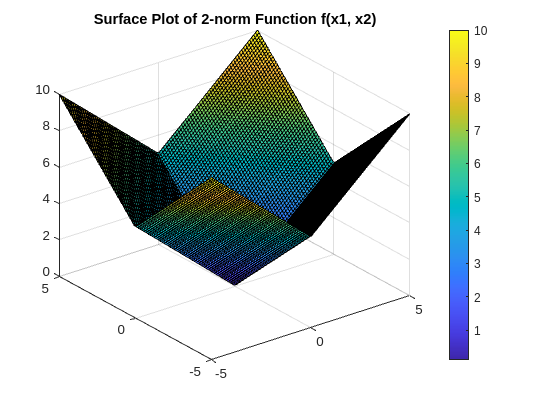


clf;
syms x1 x2;

% Define the 2-norm function
f = abs(x1)+abs(x2);
% Define the range of x1 and x2
x1_range = linspace(-5, 5, 100);
x2_range = linspace(-5, 5, 100);

[x1_grid, x2_grid] = meshgrid(x1_range, x2_range);
f_values = double(subs(f, {x1, x2}, {x1_grid, x2_grid}));
surf(x1_range, x2_range, f_values); colorbar;
title('Surface Plot of 1-norm Function f(x1, x2)');